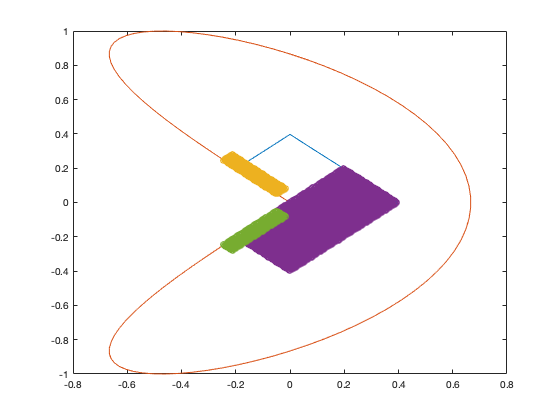

clc; clear; close all;

C = 27;
d = 4;
n_r = 6;

%% Loading FC Data
if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5));

alpha = 1./2;
beta = tan(alpha.*pi./2);
l_theta = @(theta) [-2./3.*sin(3./2.*theta), beta.*sin(theta)];

h = 5e-3;
n_C1_bound = round(0.2/h);

d = 4;

C1_patch = construct_C1_patch(f, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_C1_bound);
window_patch_xi = construct_S_patch(f, 2*pi-0.05, 2*pi-0.25, h, n_C1_bound, d+5);
window_patch_eta = construct_S_patch(f, 0.05, 0.25, h, n_C1_bound, d+5);

[boundary_X, boundary_Y] = C1_patch.boundary_mesh_xy;
figure;
plot(boundary_X, boundary_Y)
hold on;
boundary_XY = l_theta(linspace(0, 2*pi, 100)');
plot(boundary_XY(:, 1), boundary_XY(:, 2))

[X, Y] = window_patch_eta.xy_mesh;
scatter(X(:), Y(:))
[X, Y] = C1_patch.B.xy_mesh;
scatter(X(:), Y(:))
[X, Y] = window_patch_xi.xy_mesh;
scatter(X(:), Y(:))

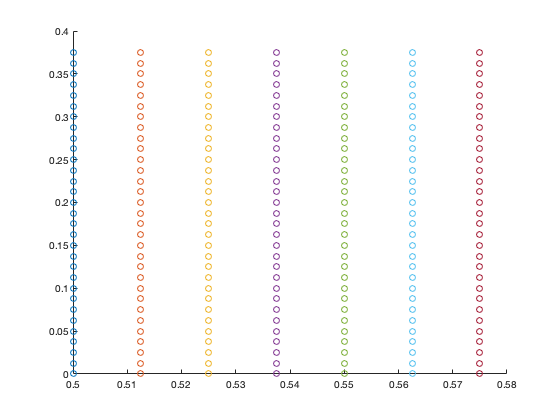

window_patch_xi =      3.000000000000045e-01


window_patch_eta =      0


converged = logical
   1


window_patch_xi =      5.000000000000000e-01


window_patch_eta =      2.249999999999992e-01


converged = logical
   1



[C1_B_norm, C1_B_c_norm, xi_norm, eta_norm] = C1_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);

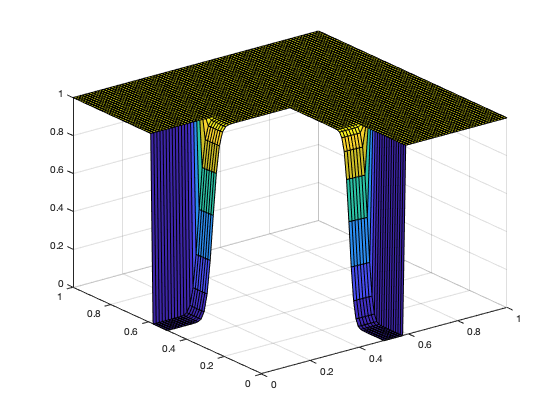


figure;
[XI, ETA] = C1_patch.B.xi_eta_mesh;
s = surf(XI, ETA, C1_patch.B.phi(XI, ETA)./C1_B_norm);
hold on;
[XI, ETA] = C1_patch.B_c.xi_eta_mesh;
s = surf(XI, ETA, C1_patch.B_c.phi(XI, ETA)./C1_B_c_norm);

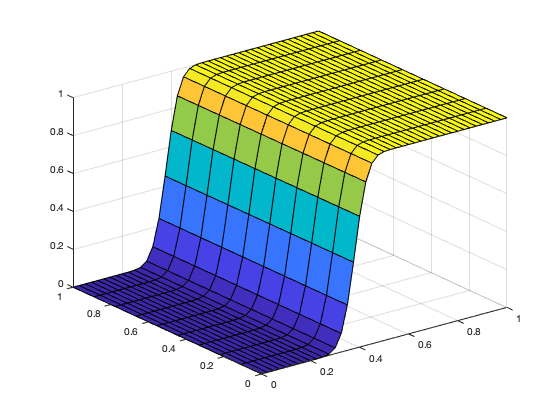


figure;
[XI, ETA] = window_patch_xi.xi_eta_mesh;
s = surf(XI, ETA, window_patch_xi.phi(XI, ETA)./xi_norm);


figure;
[XI, ETA] = window_patch_eta.xi_eta_mesh;
s = surf(XI, ETA, window_patch_eta.phi(XI, ETA)./eta_norm);

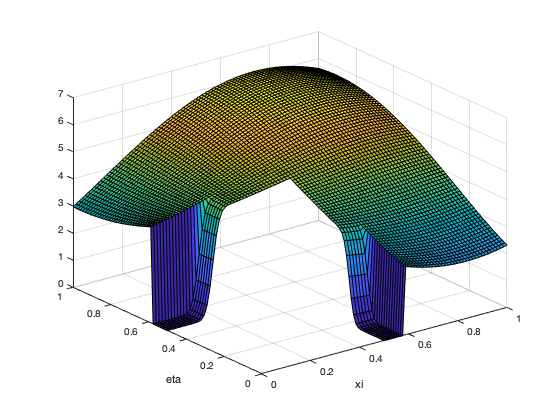


[C1_fcont_patch_xi, C1_fcont_patch_eta_refined, C1_fcont_patch_eta_unrefined, B_fcont, B_c_minus_fcont] = C1_patch.FC(C, n_r, d, A, Q, d+3, C1_B_norm, C1_B_c_norm);

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    alpha = 1./2;
    beta = tan(alpha.*pi./2);
    
    l_theta = @(theta) [-2./3.*sin(3./2.*theta), beta.*sin(theta)];
    nu_theta = @(theta) [beta.*cos(theta), cos(3./2.*theta)] ./ sqrt((beta.*cos(theta)).^2+(cos(3./2.*theta)).^2);
    l_A = @(xi) (theta_B - theta_A).*xi + theta_A;
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu_theta(l_A(xi));
    dM_pdxi = @(xi, eta, H) [
        -((-theta_A + theta_B) .* cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi))) ...
        - (beta .* eta .* H .* (-theta_A + theta_B) .* sin(theta_A + (-theta_A + theta_B) .* xi)) ...
        ./ sqrt(beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2) ...
        - (beta .* eta .* H .* cos(theta_A + (-theta_A + theta_B) .* xi) ...
        .* (-2 .* beta.^2 .* (-theta_A + theta_B) .* cos(theta_A + (-theta_A + theta_B) .* xi) .* sin(theta_A + (-theta_A + theta_B) .* xi) ...
        - 3 .* (-theta_A + theta_B) .* cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)) .* sin((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)))) ...
        ./ (2 .* (beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2).^(3./2)); ...
        
        beta .* (-theta_A + theta_B) .* cos(theta_A + (-theta_A + theta_B) .* xi) ...
        - (3 .* eta .* H .* (-theta_A + theta_B) .* sin((3./2) .* (theta_A + (-theta_A + theta_B) .* xi))) ...
        ./ (2 .* sqrt(beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2)) ...
        - (eta .* H .* cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)) ...
        .* (-2 .* beta.^2 .* (-theta_A + theta_B) .* cos(theta_A + (-theta_A + theta_B) .* xi) .* sin(theta_A + (-theta_A + theta_B) .* xi) ...
        - 3 .* (-theta_A + theta_B) .* cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)) .* sin((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)))) ...
        ./ (2 .* (beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2).^(3./2));
    ];
    
    dM_pdeta = @(xi, eta, H) [
        (beta .* H .* cos(theta_A + (-theta_A + theta_B) .* xi)) ...
            ./ sqrt(beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2); ...
        (H .* cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi))) ...
            ./ sqrt(beta.^2 .* cos(theta_A + (-theta_A + theta_B) .* xi).^2 + cos((3./2) .* (theta_A + (-theta_A + theta_B) .* xi)).^2);
    ];
    
    J = @(v, H) [dM_pdxi(v(1), v(2), H), dM_pdeta(v(1), v(2), H)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    
    XY = M_p_general(XI(:), ETA(:), h.*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end

function C1_patch = construct_C1_patch(f, theta_A, theta_B, theta_C, theta_D, theta_E, n_bound)
    alpha = 1./2;
    beta = tan(alpha.*pi./2);
    
    l_theta = @(theta) [-2./3.*sin(3./2.*theta), beta.*sin(theta)];
    l_A = @(xi) (theta_D - theta_A)*xi + theta_A;
    l_B = @(eta) (theta_E - theta_B)*eta + theta_B;
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    
    dM_pdxi = @(xi, eta) [-((-theta_A+theta_D)*cos(3/2*(theta_A+(-theta_A+theta_D)*xi))); beta*(-theta_A+theta_D)*cos(theta_A+(-theta_A+theta_D)*xi)];
    dM_pdeta = @(xi, eta) [-((-theta_B+theta_E)*cos(3/2*(theta_B+(-theta_B+theta_E)*eta))); beta*(-theta_B+theta_E)*cos(theta_B+(-theta_B+theta_E)*eta)];

    J = @(v) [dM_pdxi(v(1), v(2)), dM_pdeta(v(1), v(2))];
    C1_patch = C1_patch_obj(M_p, J, n_bound, nan, nan, nan);
    
    [X_B, Y_B] = C1_patch.B.xy_mesh;
    C1_patch.B.f_XY = f(X_B, Y_B);
    
    [X_Bc, Y_Bc] = C1_patch.B_c.xy_mesh;
    C1_patch.B_c.f_XY = f(X_Bc, Y_Bc);
end